# DISPOSITIVO 1

### PROTOCOLLO DI COMUNICAZIONE DI DISPOSITIVO 1

- Trasmissione di numFrames simboli per numRip volte

- Si mette in attesa di ricezione per waitTime secondi

- Ricomincia la trasmissione

- Se non riceve riscontro per numAtteseMax volte, il dispositivo inivia un 'Keep Alive'. Se non riceve risposta, termina la trasmissione

### SETUP INIZIALE DI TX E RX

[OFDMParams,dataParams, GeneralParam] = helperSetParameters();
attese = 0;
endureTransmission = 1;

### TRASMISSIONE

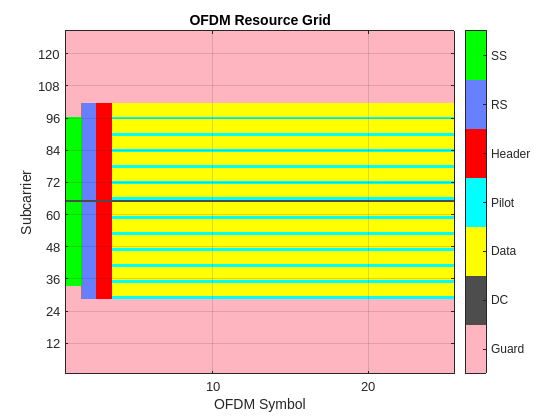

## Establishing connection to hardware. This process can take several seconds.


while endureTransmission
    GeneralParam.message = 'Hello world! ';
    helperTrasmissionModule(GeneralParam, OFDMParams, dataParams);

### ATTESA RICEZIONE

    pause(2);
    if attese ~= GeneralParam.numAtteseMax
        fprintf('Passo in ricezione\n');
        GeneralParam.carrier_frequency = GeneralParam.carrier_frequency + 0.001;
        [rxFlag, message] = helperReceiverModule(GeneralParam, OFDMParams, dataParams);
        if rxFlag
            [dataParams.coderate, dataParams.modOrder] = helperChangeParameters(message);
            fprintf('Feedback ricevuto\n Nuovi parametri:\n Mod: %d\n  CodeRate = %s\n',dataParams.modOrder, dataParams.coderate);
        else
            attese = attese + 1;
        end

### KEEP ALIVE

    else
        GeneralParam.message = 'Keep Alive';
        helperTrasmissionModule(GeneralParam, OFDMParams, dataParams);
        [rxFlag, messageReceived] = helperReceiverModule(GeneralParam, OFDMParams, dataParams);
        if ~rxFlag
            endureTransmission = 0;
        else
            dataParams = helperChangeParameters(messageReceived);
        end
    end
    GeneralParam.carrier_frequency = GeneralParam.carrier_frequency - 0.001;
end
fprintf('Trasmissione conclusa\nKeep Alive non ricevuto!\n');